w0 = 2.7802*10^4; % Hz(?)
v0 = 0.0560; % m/s

w_n = @(N) (w0*N)/pi;
v_n = @(N) v0*N;

tspan = [0, 0.005];
% N=2;
% x2 = springode45(2, w_n(N), v_n(N), tspan);
% N=3;
% x3 = springode45(3, w_n(N), v_n(N), tspan);
% N=4;
% x4 = springode45(4, w_n(N), v_n(N), tspan);
% N=5;
% x5 = springode45(5, w_n(N), v_n(N), tspan);
% N=6;
% x6 = springode45(6, w_n(N), v_n(N), tspan);
% N=7;
% x7 = springode45(7, w_n(N), v_n(N), tspan);
N=24;
x24 = springode45(24, w_n(N), v_n(N), tspan);
N=48;
x48 = springode45(48, w_n(N), v_n(N), tspan);
N=96;
x96 = springode45(96, w_n(N), v_n(N), tspan);
% N=192;
% x192 = springode45(192, w_n(N), v_n(N), tspan);
% N=384;
% x384 = springode45(384, w_n(N), v_n(N), tspan);

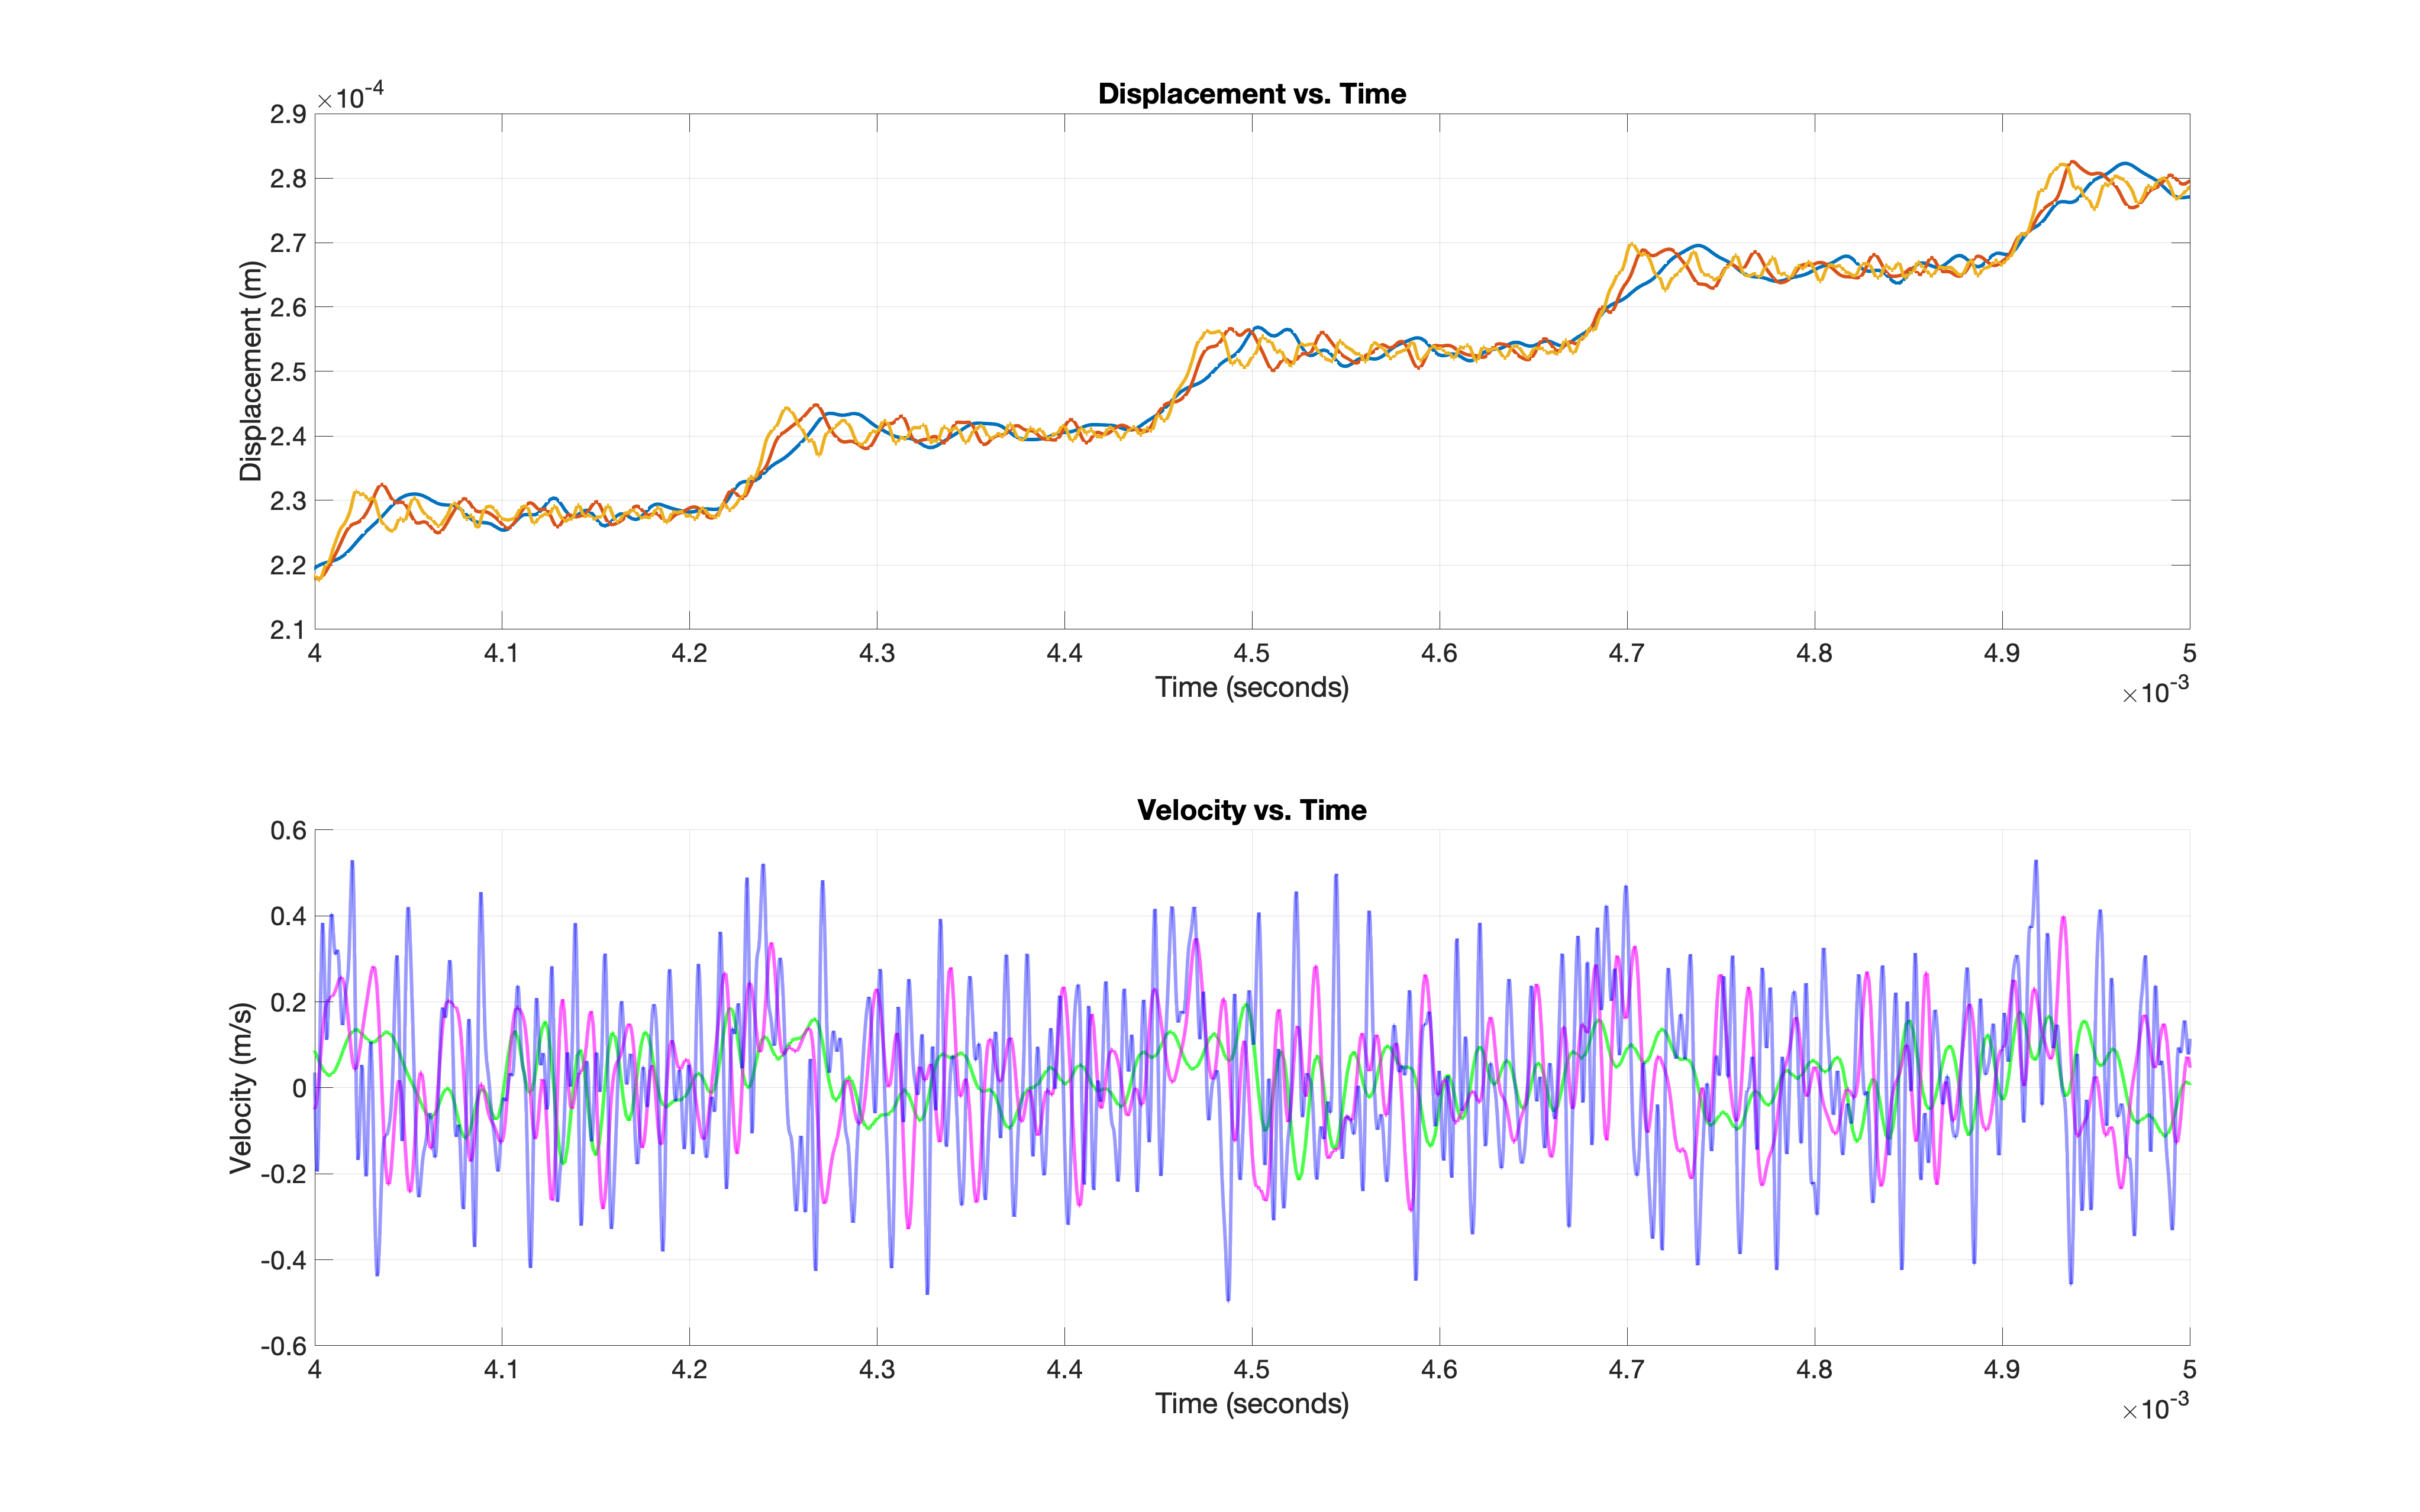

offset = 0.05*10^-3;
v_scale = 0.4;

close all
fontsize = 22;
figure(3)
subplot(2,1,1)
set(gcf,'units','normalized','position',[0 0 1.8 1.8]);
plot(x24.t_spr+offset, x24.du_spr,'LineWidth',3)
hold on
plot(x48.t_spr+offset, x48.du_spr,'LineWidth',3)
plot(x96.t_spr+offset, x96.du_spr,'LineWidth',3)
% plot(x192.t_spr+offset, x192.du_spr,'LineWidth',3)
% plot(x384.t_spr+offset, x384.du_spr,'LineWidth',3)
hold off
title('Displacement vs. Time')
xlabel('Time (seconds)')
ylabel('Displacement (m)')
xlim([0.004 0.005])
grid on
set(gca,'FontSize',fontsize)

subplot(2,1,2)
patchline(x24.t_spr+offset,x24.v_spr*v_scale,'linestyle','-','edgecolor','g','linewidth',3,'edgealpha',0.7)
patchline(x48.t_spr+offset,x48.v_spr*v_scale,'linestyle','-','edgecolor','m','linewidth',3,'edgealpha',0.6)
hold on
patchline(x96.t_spr+offset,x96.v_spr*v_scale,'linestyle','-','edgecolor','b','linewidth',3,'edgealpha',0.4)
% patchline(x192.t_spr+offset,x192.v_spr*v_scale,'linestyle','-','edgecolor','r','linewidth',3,'edgealpha',0.3)
% patchline(x384.t_spr+offset,x384.v_spr*v_scale,'linestyle','-','edgecolor','c','linewidth',3,'edgealpha',0.2)
hold off
title('Velocity vs. Time')
xlabel('Time (seconds)')
ylabel('Velocity (m/s)')
xlim([0.004 0.005])
grid on
set(gca,'FontSize',fontsize)

% legend('1 spring', '2 springs',
%'3 springs', '4 springs', '5 springs')
% omega*N/pi